# Construction of New Gait Library (no symmetry assumption)

The following MATLAB Live Script builds a new gait library (gait_library_4) based on gaits B, G, I, J, K for the orange robot with threaded fishing line for the tendons of the motor-tendon actuators. The last three gaits (I,J,K) are based on symmetric permutations of gait G (i.e., gait G actuation sequence has been succesively rotated by 90 degrees). If the robot is symmetric, this should produce gaits that are identical but with trajectories at four distinct angles offset by 90 degrees (NW, SW, SE, NE). 

The results show that the robot is not symmetric. While the symmetric permutations do roughly produce trajectories in these four directions, they have different velocities and radii of curvature. Therefore, we can construct a new gait library to encode these unique twists and incorporate them into the path planning algorithm.

% Dependencies:
%   +demos/data/visualtracking
%   +offlineanalysis/GaitTest
%   +gaitdef/Gait

% [0] == Script setup
clear; clc; close all

% Add dependencies to classpath
addpath('../');
addpath('data/visualtracking/orange MTA4 threaded');

% Configure figure tex interpreters
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');
set(0, 'DefaultAxesFontSize', 18);

% Decide which figures to show.
show_markers = true;     % plots first frame of each video
show_gait_sequences = true;      % Visualizes the discrete robot configurations in each gait sequence.

## List all experiment data filenames.

####  From 20230224 Experiments:

    Gait B-60 [32SR - not following - left]

gait_names{1}  = 'B_60_32SR_NF_L_1.mat';   

    Gait B-60 [32SR - not following - left]

gait_names{2}  = 'B_60_32SR_NF_L_2.mat';   

    Gait G-60 [32SR - not following - left]

gait_names{3}  = 'G_60_32SR_NF_L_1.mat';   

    Gait G-60 [32SR - not following - left]

gait_names{4}  = 'G_60_32SR_NF_L_2.mat';   

    Gait I-60 [32SR - not following - left]

gait_names{5}  = 'I_60_32SR_NF_L_1.mat';   

    Gait I-60 [32SR - not following - left]

gait_names{6}  = 'I_60_32SR_NF_L_2.mat';  

    Gait J-60 [32SR - not following - left]

gait_names{7}  = 'J_60_32SR_NF_L_1.mat';   

    Gait J-60 [32SR - not following - left]

gait_names{8}  = 'J_60_32SR_NF_L_2.mat';  

    Gait K-60 [32SR - not following - left]

gait_names{9}  = 'K_60_32SR_NF_L_1.mat';   

    Gait K-60 [32SR - not following - left]

gait_names{10}  = 'K_60_32SR_NF_L_2.mat';  

####  From 20230224 Experiments:

 Gait L-60 [32SR - not following - left]

gait_names{11}  = 'L_60_32SR_NF_L_1.mat';   

    Gait L-60 [32SR - not following - left]

gait_names{12}  = 'L_60_32SR_NF_L_2.mat';   

    Gait M-60 [32SR - not following - left]

gait_names{13}  = 'M_60_32SR_NF_L_1.mat';   

    Gait M-60 [32SR - not following - left]

gait_names{14}  = 'M_60_32SR_NF_L_2.mat';   

    Gait N-60 [32SR - not following - left]

gait_names{15}  = 'N_60_32SR_NF_L_1.mat';   

    Gait N-60 [32SR - not following - left]

gait_names{16}  = 'N_60_32SR_NF_L_2.mat';  

## Extract and define parameters for GaitTest() objects.

n_gaits = length(gait_names);
% Define experimental parameters after investigating videos. 
frame_start_list(1:6) = [58,62,26,46,54,58];
frame_start_list(7:10) = [78,97,42,42];
frame_start_list(11:16) = [36,49,92,50,53,57];
% Find marker order by investigating first frame.
marker_order_list = repmat([2 3 4 1],n_gaits, 1);
marker_order_list([4,5,6,10],:) = repmat([2 4 3 1],4,1);
marker_order_list([8,13],:) = repmat([1 3 4 2],2,1);

### Build Experiment Matrix

if isrow(gait_names)
    gait_names = gait_names';
end

% Extract characteristics of each gait test.
file_names = split(gait_names, '.');
gait_characteristics = cell(n_gaits, 7);
for i = 1:n_gaits
    gait_characteristics(i, 1) = num2cell(i);
    n_underscores = count(gait_names{i}, '_');
    if n_underscores == 4
        gait_characteristics(i, 2:6) = split(file_names(i,1), '_');
        gait_characteristics(i, 7) = num2cell(1);
    else
        gait_characteristics(i, 2:7) = split(file_names(i,1), '_');
    end
end
characteristics = ["Experiment", "Gait", "#Cycles", "Tether", ...
              "Protocol", "Placement", "Trial"];
% Build table.
experiments = cell2table(gait_characteristics, "VariableNames", ...
              characteristics);
sorted_exps = sortrows(experiments, characteristics([2, 4, 5, 6, 7]))

sorted_exps = 16×7 table
    Experiment    Gait     #Cycles     Tether     Protocol    Placement    Trial
    __________    _____    _______    ________    ________    _________    _____

         1        {'B'}    {'60'}     {'32SR'}     {'NF'}       {'L'}      {'1'}
         2        {'B'}    {'60'}     {'32SR'}     {'NF'}       {'L'}      {'2'}
         3        {'G'}    {'60'}     {'32SR'}     {'NF'}       {'L'}      {'1'}
         4        {'G'}    {'60'}     {'32SR'}     {'NF'}       {'L'}      {'2'}
         5        {'I'}    {'60'}     {'32SR'}     {'NF'}       {'L'}      {'1'}
         6        {'I'}    {'60'}     {'32SR'}     {'NF'}       {'L'}      {'2'}
         7        {'J'}    {'60'}     {'32SR'}     {'NF'}       {'L'}      {'1'}
       

% Construct titles. 
title_components = string(gait_characteristics);
title_components(strcmp(experiments.Tether, 'H'), 4) = 'heavy sheath';
title_components(strcmp(experiments.Tether, 'S'), 4) = 'light sheath';
title_components(strcmp(experiments.Tether, 'NS'), 4) = 'no sheath';
title_components(strcmp(experiments.Tether, '32'), 4) = '32 AWG';
title_components(strcmp(experiments.Tether, '32SR'), 4) = '32 AWG with slip ring';
title_components(strcmp(experiments.Tether, '32SR1'), 4) = '32 AWG with old slip ring';
title_components(strcmp(experiments.Protocol, 'F'), 5) = 'following';
title_components(strcmp(experiments.Protocol, 'NF'), 5) = 'not following';
title_components(strcmp(experiments.Placement, 'L'), 6) = 'left';
title_components(strcmp(experiments.Placement, 'R'), 6) = 'right';
title_components = [repmat(["Experiment" ":" "cycles of Gait" "with" "tether (" "," ")," "trial"], n_gaits, 1) title_components];
title_matrix = title_components(:, [1,9,2,11,3,10,4,12,5,14,6,13,7,8,15]);
exp_title = join(title_matrix);

% Initialize the stability experiment struct. 
stab_exp = struct('params', [], 'raw_data', []);
gait_sequences = cell(n_gaits,1);

% Extract data.
for i = 1:n_gaits
    % Define robot / experiment parameters.
    stab_exp(i).params.robot_name = 'orange threaded';
    stab_exp(i).params.substrate = 'black mat';
    stab_exp(i).params.n_markers = 4;
    stab_exp(i).params.pixel_length = 1/8.6343;     % cm per pixel

    % Define number of gait cycles run.
 
    

        stab_exp(i).params.n_cycles= str2double(gait_characteristics{i,3});


    % Extract and store first frame information.
    stab_exp(i).params.frame_1 = frame_start_list(i);
    stab_exp(i).params.marker_order = marker_order_list(i,:);
    
    % Extract and store raw data from each trial
    filename = gait_names{i};
    stab_exp(i).raw_data = load(filename).tracking_data;  
    switch experiments.Gait{i}
        case 'B'
            gait_sequences{i} = [16,7,5,11,14];   % Gait B (rotational)
        case 'E'
            gait_sequences{i} = [9,16,1];         % Gait E (translational)
        case'Bs'
            gait_sequences{i} = [8,7,5,3,6];
        case'Es' 
            gait_sequences{i} = [9,12,1];
        case 'F'
            gait_sequences{i} = [9 14 8 1];
        case 'G' 
            gait_sequences{i} = [3 15 1];
        case 'H'
            gait_sequences{i} = [7 12 13 2];
        case 'I'
            gait_sequences{i} = [2 8 1];
        case 'J'
            gait_sequences{i} = [9 12 1];
        case 'K'
            gait_sequences{i} = [5 14 1];
        case 'L'
            gait_sequences{i} = [16 1];
        case 'M'
            gait_sequences{i} = [9 5 3 2];
        case 'N'
            gait_sequences{i} = [13 16 4 1];
        otherwise
            gait_sequences{i} = [];
    end
    gait_sequences{4} = [1, 16, 1];
end

## Analyze the experiment data:

#### 1. Rotate the data w.r.t. the initial global orientation.

% Define first experiment first frame orientation as theta = 0. 
markers_x(1, :) = stab_exp(1).raw_data(1, 1:3:stab_exp(1).params.n_markers*3-2);
markers_y(1, :) = stab_exp(1).raw_data(1, 2:3:stab_exp(1).params.n_markers*3-1);
centroid(:, :, 1) = mean([markers_x(1, :); markers_y(1, :)], 2);
% Move initial position to (0,0) origin.
reference_markers = [markers_x(1, marker_order_list(1,:)); markers_y(1, marker_order_list(1,:));]...
                    - centroid(:, :, 1);
% For each trial, rotate data to align first frame global orientations.
 for i = 1:n_gaits
    % Find initial rotation matrix for each trial to have consistent fixed frame.
    markers_x(i, :) = stab_exp(i).raw_data(1, 1:3:stab_exp(i).params.n_markers*3-2);
    markers_y(i, :) = stab_exp(i).raw_data(1, 2:3:stab_exp(i).params.n_markers*3-1);
    centroid(:, :, i) = mean([markers_x(i, :); markers_y(i, :)], 2);

    % Move initial position to (0,0) origin.
    shifted_markers = [markers_x(i, stab_exp(i).params.marker_order);
                       markers_y(i, stab_exp(i).params.marker_order)]...
                       - centroid(:, :, i);

    % Find orientation of subsequent trials w.r.t. first trial GCS.
    [regParams,~,~] = absor(reference_markers, shifted_markers);
    stab_exp(i).params.R_1 = [regParams.R zeros(2,1); 0 0 1];
 end


#### 2. Instantiate GaitTest() objects for each experimental trial.

 %This analyzes the data from each trial to find motion primitive twist information.
% Instantiate objects for each gait tested. 
all_gaits = offlineanalysis.GaitTest.empty(0,n_gaits); 
gait_defs = gaitdef.Gait.empty(0,n_gaits);
tail_idx = cell(n_gaits, 1);
head_idx = cell(n_gaits, 1);
delta_poses = cell(n_gaits,1);
global_theta = cell(n_gaits,1);
twists = cell(n_gaits,1);
cent_rot = cell(n_gaits,1);
rad_curv = cell(n_gaits,1);
orientation = cell(n_gaits,1);
global_change = cell(n_gaits,1);
total_dist = cell(n_gaits,1);

#### 3. Calculate twists for each gait experiment.

% Calculate twists for each gait experiment.
for i = 1:n_gaits
    all_gaits(i) = offlineanalysis.GaitTest(stab_exp(i).raw_data, ...
                                                 gait_sequences{i}(1,:), ...
                                                 stab_exp(i).params);
    gait_defs(i) = gaitdef.Gait(all_gaits(i), stab_exp(i).params);
    % Manually find the twists. 
    % Extract gait / experiment details. 
    n_cycles = all_gaits(i).n_cycles;
    len_gait = all_gaits(i).len_gait;
     for j = 1:n_cycles 
         % Record indexes for each motion primitive tail and head. 
         tail_idx{i}(1,j) = all_gaits(i).keyframes(len_gait*(j-1)+2);
         head_idx{i}(1,j) = all_gaits(i).keyframes(len_gait*j+2);

         % Find change in poses w.r.t. global inertial frame for each motion primitive. 
         delta_poses{i}(:,j) = all_gaits(i).raw_poses(:, head_idx{i}(1,j)) - all_gaits(i).raw_poses(:, tail_idx{i}(1,j));
         delta_poses{i}(1:2,j) = all_gaits(i).pixel_length*delta_poses{i}(1:2,j);

         % Find global orientation of robot at each motion primitive tail. 
         global_theta{i}(:,j) = all_gaits(i).raw_poses(3, tail_idx{i}(1,j));

         % Convert from global frame to body frame.  
         rot_mat =  [cos(global_theta{i}(1,j)) -sin(global_theta{i}(1,j)); sin(global_theta{i}(1,j)) cos(global_theta{i}(1,j))];
         delta_poses{i}(1:2,j) = rot_mat'*delta_poses{i}(1:2,j);
         R =  [cos(delta_poses{i}(3,j)) -sin(delta_poses{i}(3,j)); sin(delta_poses{i}(3,j)) cos(delta_poses{i}(3,j))];
         % Convert to twists.
         twists{i}(:,j)  = gait_defs(i).delta_pose_2_twist(delta_poses{i}(:,j), all_gaits(i).transition_time*len_gait);

         % Find instantaneous center of rotation.
         cent_rot{i}(:,j) = (eye(2) - R)\delta_poses{i}(1:2, j);

         % Find instantaneous radius of curvature.
         rad_curv{i}(1,j) = norm(cent_rot{i}(:,j));
     end
      lin_vel{i} = (twists{i}(1,:).^2+twists{i}(2,:).^2).^.5;
end


## Construct comparative ICR / ROC plots.

## Make gait library.

unique_gait_names = '';
for i = 1:8
    gait_lib_threaded(i) = gaitdef.Gait(all_gaits([2*i-1,2*i]));
    gait_lib_threaded(i).gait_name = gait_names{2*i}(1);
    unique_gait_names(i) = gait_names{2*i}(1);
    gait_lib_threaded(i).robot_name = all_gaits(2*i).robot_name;
    gait_lib_threaded(i).tether = '32SR';
    gait_lib_threaded(i).tether = {'NF (left)','NF (left)'};
end

## Plot gait libraries.

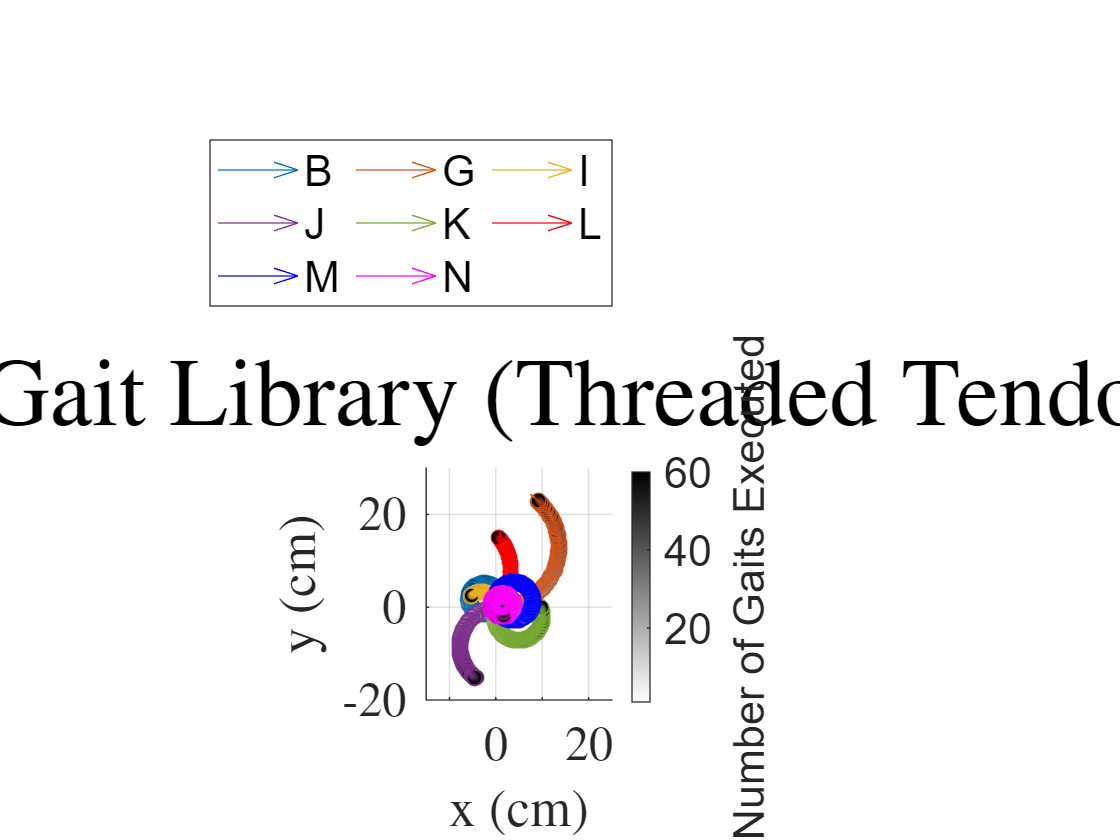

%%
figure
plot_trajs(gait_lib_threaded, 1:length(gait_lib_threaded), {'B','G','I','J','K','L','M','N'}, 10,60)
% save data/gait_lib_threaded gait_lib_threaded
 xlim([-15,25])
ylim([-20,30])
title('New Gait Library (Threaded Tendons)', 'Interpreter','latex','FontSize',36)

## Plot gait characterization.

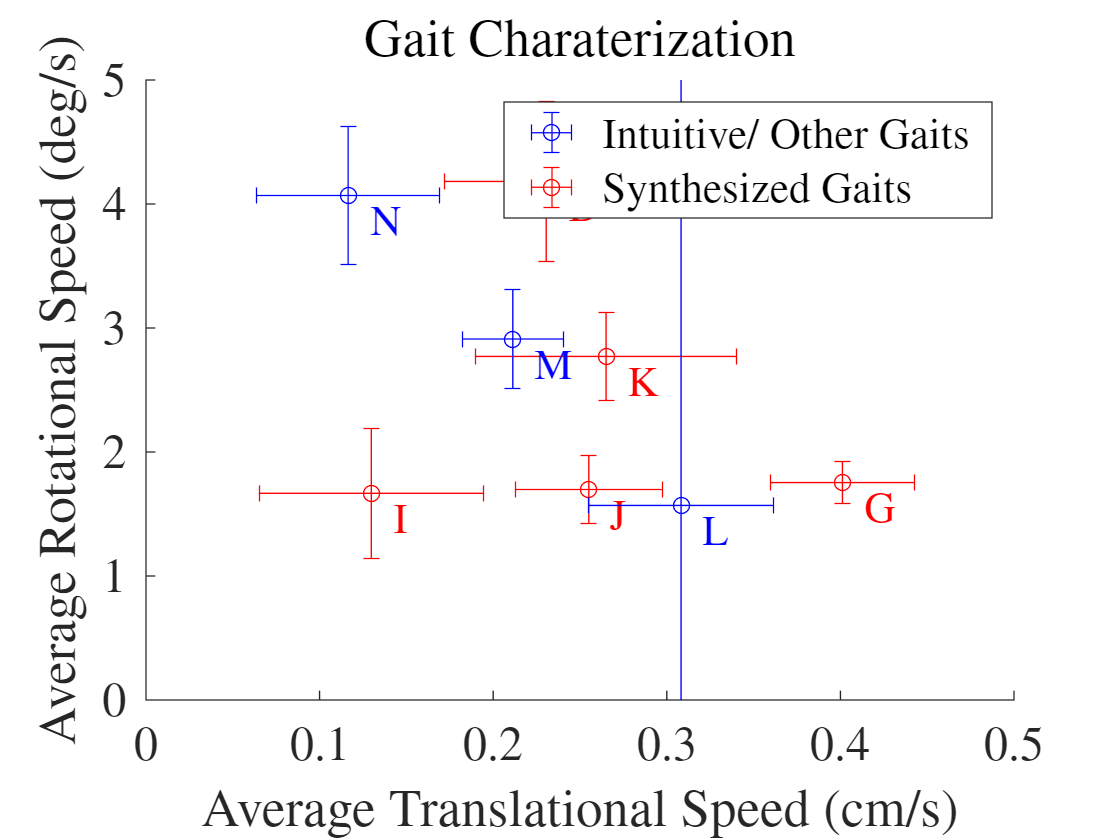

for i = 1:floor(n_gaits/2)
     avg_lin_speed(1,i) = mean([lin_vel{2*i-1} lin_vel{2*i}]);
     err_lin_speed(1,i) = var([lin_vel{2*i-1} lin_vel{2*i}]).^.5;
     avg_rot_speed(1,i) = abs(rad2deg(mean([twists{2*i-1}(3,:) twists{2*i}(3,:)])));
     err_rot_speed(1,i) = rad2deg(var([twists{2*i-1}(3,:) twists{2*i}(3,:)]).^.5);
end
speed_data = [avg_lin_speed; err_lin_speed; avg_rot_speed; err_rot_speed];

%figure('Renderer', 'painters', 'Position', [10 10 1920 1080])
figure
hold on
plot_gait_char(1:5,unique_gait_names(1:5), speed_data,1)
plot_gait_char(6:8,unique_gait_names(6:8), speed_data,0)
ylim([0 5])
xlim([0 .5])
title('Gait Charaterization', 'FontSize',20)
ax = gca;
legend([ax.Children(4), ax.Children(10)],["Intuitive/ Other Gaits", "Synthesized Gaits"],'Interpreter','latex')

## Construct comparative motion plots.

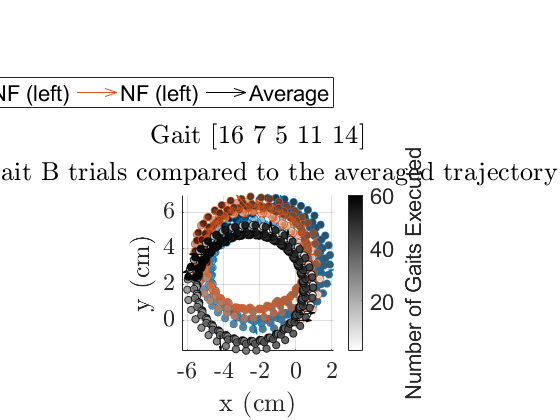

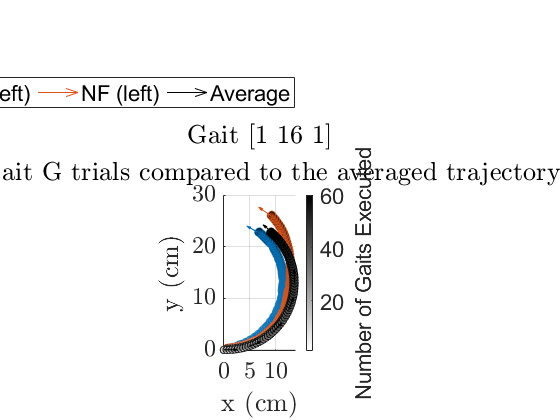

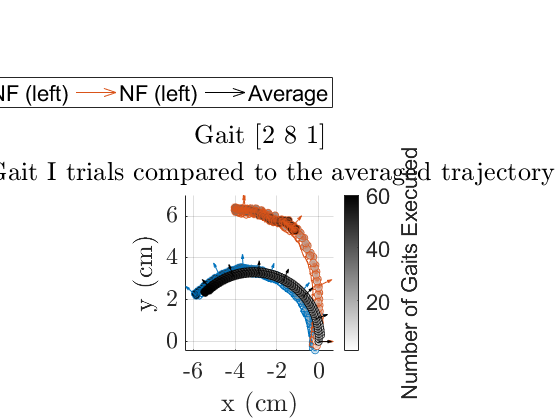

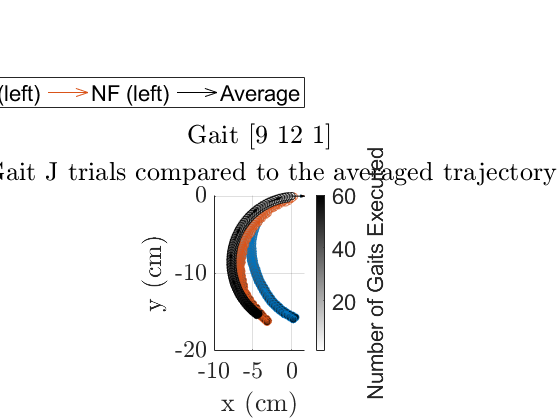

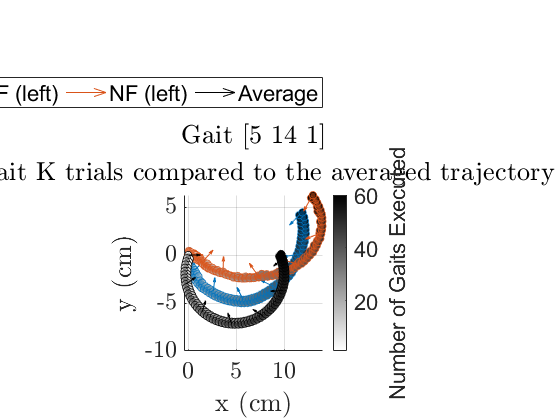

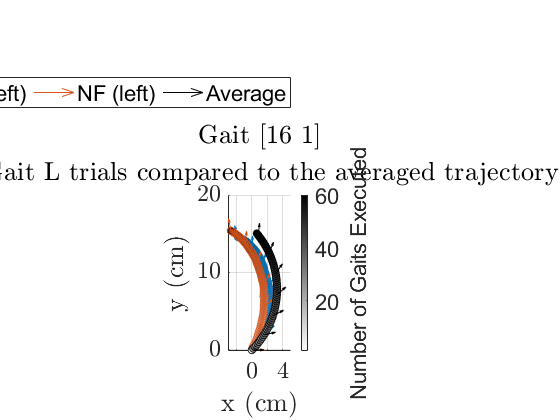

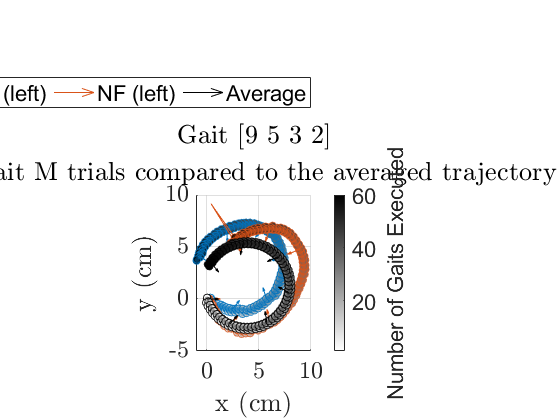

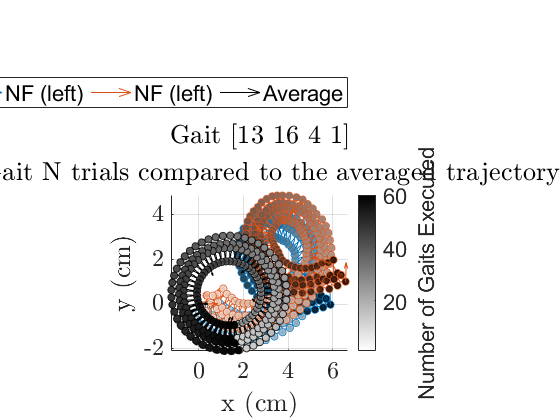

for i = 1:floor(n_gaits/2)
    figure
    trial_nums = 2*i-1:2*i;
    trial_labels = {'NF (left)','NF (left)'};
    plot_trajs(all_gaits, trial_nums, trial_labels, 15)
    hold on
    plot_trajs(gait_lib_threaded, i, {'Average'}, 15,60,'k')
    ax = gca;
    lgd_idxs = [];
    for j = 1:4:length(ax.Children)
        lgd_idxs = [lgd_idxs ax.Children(j)];
    end
    legend(flip(lgd_idxs),{'NF (left)','NF (left)','Average'})
    subtitle(['2 Gait ' gait_lib_threaded(i).gait_name ' trials compared to the averaged trajectory'])
end

## Construct comparative twist plots.

Twist comparison for 2 trials of gait B (AWG 32 with new slip ring):

% twists_plot =plot_twists(twists, global_theta, trial_nums_B_32SR, trial_labels_B_32SR,[0 0.6;0 0.6; 0.06 0.12; 0 0.6; 0 0.6; 0.06 0.12 ]);
% hold on
% nexttile(1)
% plot(1:60, gait_lib_threaded(1).Twist(1)*ones(60,1),'k');
% nexttile(3)
% plot(1:60, gait_lib_threaded(1).Twist(2)*ones(60,1),'k');
% nexttile(5)
% plot(1:60, gait_lib_threaded(1).Twist(3)*ones(60,1),'k');
% nexttile(2)
% plot([-180, 180],gait_lib_threaded(1).Twist(1)*ones(2,1),'k')
% nexttile(4)
% plot([-180, 180],gait_lib_threaded(1).Twist(2)*ones(2,1),'k')
% nexttile(6)
% plot([-180, 180],gait_lib_threaded(1).Twist(3)*ones(2,1),'k')
% legend({'NF (left)','NF (right)','Average'})
% t = title(twists_plot, 'Gait B Twists');
% t.FontSize = 20;
% t.Interpreter = 'latex';

Twist comparison for 5 trials of gait G (AWG 32 with new slip ring):

% twists_plot = plot_twists(twists, global_theta, trial_nums_G_32SR, trial_labels_G_32SR,[0 0.6; -.3 .3; 0 0.05; 0 0.6; -.3 .3; 0 0.06]);
% hold on
% nexttile(1)
% plot(1:60, gait_lib_threaded(2).Twist(1)*ones(60,1),'k');
% nexttile(3)
% plot(1:60, gait_lib_threaded(2).Twist(2)*ones(60,1),'k');
% nexttile(5)
% plot(1:60, gait_lib_threaded(2).Twist(3)*ones(60,1),'k');
% nexttile(2)
% plot([-180, 180],gait_lib_threaded(2).Twist(1)*ones(2,1),'k')
% nexttile(4)
% plot([-180, 180],gait_lib_threaded(2).Twist(2)*ones(2,1),'k')
% nexttile(6)
% plot([-180, 180],gait_lib_threaded(2).Twist(3)*ones(2,1),'k')
% legend({'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})
% t = title(twists_plot, 'Gait G Twists');
% t.FontSize = 20;
% t.Interpreter = 'latex';

Twist comparison for 5 trials of gait I (AWG 32 with new slip ring):

% twists_plot = plot_twists(twists, global_theta, trial_nums_I_32SR, trial_labels_I_32SR,[-.3 .3; -.2 .4; .01 .07; -.3 .3; .15 .4; .01 .07]);
% hold on
% nexttile(1)
% plot(1:60, gait_lib_threaded(3).Twist(1)*ones(60,1),'k');
% nexttile(3)
% plot(1:60, gait_lib_threaded(3).Twist(2)*ones(60,1),'k');
% nexttile(5)
% plot(1:60, gait_lib_threaded(3).Twist(3)*ones(60,1),'k');
% nexttile(2)
% plot([-180, 180],gait_lib_threaded(3).Twist(1)*ones(2,1),'k')
% nexttile(4)
% plot([-180, 180],gait_lib_threaded(3).Twist(2)*ones(2,1),'k')
% nexttile(6)
% plot([-180, 180],gait_lib_threaded(3).Twist(3)*ones(2,1),'k')
% legend({'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})
% t = title(twists_plot, 'Gait I Twists');
% t.FontSize = 20;
% t.Interpreter = 'latex';

Twist comparison for 5 trials of gait J (AWG 32 with new slip ring):

% twists_plot = plot_twists(twists, global_theta, trial_nums_J_32SR, trial_labels_J_32SR,[-.5 .1;-.5 .1;.01 .07; -.5 .1;-.5 .1;.01 .07]);
% hold on
% nexttile(1)
% plot(1:60, gait_lib_threaded(4).Twist(1)*ones(60,1),'k');
% nexttile(3)
% plot(1:60, gait_lib_threaded(4).Twist(2)*ones(60,1),'k');
% nexttile(5)
% plot(1:60, gait_lib_threaded(4).Twist(3)*ones(60,1),'k');
% nexttile(2)
% plot([-180, 180],gait_lib_threaded(4).Twist(1)*ones(2,1),'k')
% nexttile(4)
% plot([-180, 180],gait_lib_threaded(4).Twist(2)*ones(2,1),'k')
% nexttile(6)
% plot([-180, 180],gait_lib_threaded(4).Twist(3)*ones(2,1),'k')
% legend({'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})
% t = title(twists_plot, 'Gait J Twists');
% t.FontSize = 20;
% t.Interpreter = 'latex';

Twist comparison for 5 trials of gait K (AWG 32 with new slip ring):

% twists_plot = plot_twists(twists, global_theta, trial_nums_K_32SR, trial_labels_K_32SR,[-.3 .3;-.6 0;0 .06; -.3 .3;-.6 0;0 .06]);
% hold on
% nexttile(1)
% plot(1:60, gait_lib_threaded(5).Twist(1)*ones(60,1),'k');
% nexttile(3)
% plot(1:60, gait_lib_threaded(5).Twist(2)*ones(60,1),'k');
% nexttile(5)
% plot(1:60, gait_lib_threaded(5).Twist(3)*ones(60,1),'k');
% nexttile(2)
% plot([-180, 180],gait_lib_threaded(5).Twist(1)*ones(2,1),'k')
% nexttile(4)
% plot([-180, 180],gait_lib_threaded(5).Twist(2)*ones(2,1),'k')
% nexttile(6)
% plot([-180, 180],gait_lib_threaded(5).Twist(3)*ones(2,1),'k')
% legend({'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})
% t = title(twists_plot, 'Gait K Twists');
% t.FontSize = 20;
% t.Interpreter = 'latex';

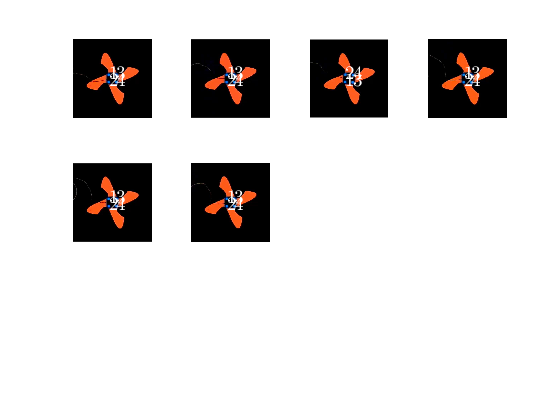


if show_markers
    figure
    %tiledlayout(5,6)
    tiledlayout(3,4)
    for i = 11:16
    
    pic_name = gait_names{i};
    pic_name(end-3:end) = [];
    % Plot first image of experiment video.
    file_name = ['data/visualtracking/orange MTA4 threaded/firstframe_', pic_name, '.jpg'];
    pic = imread(file_name);
    nexttile;
    imshow(pic)
    hold on
    
    % Plot labeled (i.e., numbered) markers on top of image.
    markers_x(i, :) = stab_exp(i).raw_data(1, 1:3:stab_exp(i).params.n_markers*3-2);
    markers_y(i, :) = stab_exp(i).raw_data(1, 2:3:stab_exp(i).params.n_markers*3-1);
%     if iTrial ~=5
    for m = 1:stab_exp(i).params.n_markers
        text(markers_x(i, m), 1080-markers_y(i, m), num2str(m),'Color','white','FontSize',14);
%     end
    end
    
    % Adjust size.
     xlim([min(markers_x(i, :))-200, max(markers_x(i, :))+200]);
     ylim([min(1080 - markers_y(i, :)) - 200, max(1080 - markers_y(i, :))+200]);
    
    
end
end

## Show graphical representations of gait sequences.

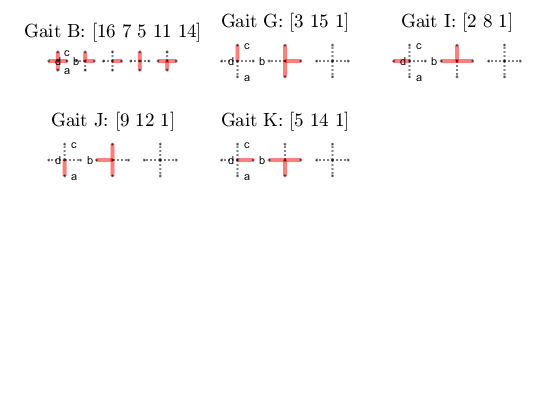

if show_gait_sequences
    %I = imread('MTA3_Black_Mat.jpg');
    figure
    n_limbs = log2(all_gaits(1).n_unique_states);    % number of robot limbs
    state_map = dec2bin(0:all_gaits(1).n_unique_states-1);
    T = tiledlayout(4,3);
    T.TileSpacing = 'compact';
    T.Padding = 'compact';
    gait_order = char(experiments.Gait);
    [~,gait_idx,~] = unique(gait_order,'stable');
    %gait_idx = sort(gait_idx);
    % Make adjacency matrix for the graphs. 
    adj_mat = zeros(n_limbs+1);
    adj_mat(2:end,1) = ones(n_limbs, 1);
    adj_mat(1,2:end) = ones(1, n_limbs);

    for i = 1:5 %21
        nexttile(T,i);
        % String of robot states for a given gait.
        states = gait_sequences{gait_idx(i)};
        len_gait = length(states);
        seq = join(string(states));
        rep_adj_mat = repmat({adj_mat},1,len_gait);
        Adj_Mat = blkdiag(rep_adj_mat{:});
        n_nodes = length(Adj_Mat);
        G = graph(Adj_Mat);
        h = plot(G,'k:.','LineWidth',1.5);
        n_edges = len_gait*n_limbs;
        edge_logic = str2num(reshape(transpose(state_map(states,:)),n_edges,1));
        n_act = nnz(edge_logic);
        
        off_idx = find(~edge_logic);
        G_act = G;
        G_act = rmedge(G_act,off_idx);
        highlight(h,G_act,'EdgeColor','r','LineWidth',3,'LineStyle','-')

        XData = [0 0 1 0 -1];
        for j = 1:len_gait-1
           XData = [XData (XData(end-4:end)+3)];
        end
        h.XData = XData;
        h.YData = repmat([0 -1 0 1 0],1,len_gait);
        h.ZData = zeros(1,n_nodes);
        node_labels = repmat({''},1,n_nodes);
        node_labels(2:n_limbs+1) = {'a', 'b', 'c','d'};
        labelnode(h,1:n_nodes,node_labels);
        axis equal
        xlim([-inf inf]) 
        ylim([-1.5 1.5])
        axis off
        title("Gait "+experiments.Gait(gait_idx(i))+": ["+seq +"]", 'FontSize',14)
    end
    states_new = {[16,1];[9,5,3,2];[13,16,4,1]};
         names_new = {'L','M','N'}; 
   for i = []%9:11

       nexttile(T,i);
        % String of robot states for a given gait.
        states = states_new{i-8};
        len_gait = length(states);
        seq = join(string(states));
        rep_adj_mat = repmat({adj_mat},1,len_gait);
        Adj_Mat = blkdiag(rep_adj_mat{:});
        n_nodes = length(Adj_Mat);
        G = graph(Adj_Mat);
        h = plot(G,'k:.','LineWidth',1.5);
        n_edges = len_gait*n_limbs;
        edge_logic = str2num(reshape(transpose(state_map(states,:)),n_edges,1));
        n_act = nnz(edge_logic);
        
        off_idx = find(~edge_logic);
        G_act = G;
        G_act = rmedge(G_act,off_idx);
        highlight(h,G_act,'EdgeColor','r','LineWidth',3,'LineStyle','-')

        XData = [0 0 1 0 -1];
        for j = 1:len_gait-1
           XData = [XData (XData(end-4:end)+3)];
        end
        h.XData = XData;
        h.YData = repmat([0 -1 0 1 0],1,len_gait);
        h.ZData = zeros(1,n_nodes);
        node_labels = repmat({''},1,n_nodes);
        node_labels(2:n_limbs+1) = {'a', 'b', 'c','d'};
        labelnode(h,1:n_nodes,node_labels);
        axis equal
        xlim([-inf inf]) 
        ylim([-1.5 1.5])
        axis off
        title("Gait "+names_new(i-8)+": ["+seq +"]", 'FontSize',14)

    end
end

function plot_trajs(all_gaits, trial_nums, trial_labels, marker_size, n_cycles, color_array)
if nargin<5
    n_cycles = [];
    color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30","#FF0000",	"#0000FF",	"#FF00FF"];
end
if nargin<6
    color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#FF0000",	"#0000FF",	"#FF00FF"];
end
k = 1;
lgd_idxs = [];
for i = trial_nums
    if isempty(n_cycles)
        all_gaits(i).plot;
    else
        all_gaits(i).plot(n_cycles);
    end
    ax = gca;
    if isprop(ax.Children(1), "Color")
        ax.Children(1).Color = color_array(k);
    else
       % ax.Children(1).CData = color_array(k);
    end
    ax.Children(2).MarkerEdgeColor = "none";
    ax.Children(2).MarkerFaceColor = color_array(k); 
    ax.Children(2).MarkerFaceAlpha = .3;
    ax.Children(2).MarkerFaceAlpha = .3;
    ax.Children(3).MarkerEdgeColor = color_array(k);
    ax.Children(3).MarkerEdgeAlpha = .8;
    if isprop(ax.Children(4), "Color")
        ax.Children(4).Color = color_array(k);
    else
        %ax.Children(4).CData = color_array(k);
    end
    if ~isempty(marker_size)
        ax.Children(2).SizeData = marker_size;
    end
    k = k+1;
    lgd_idxs = [lgd_idxs ax.Children(1)];
end
colormap(flip(gray))
a = colorbar;
a.Location = "eastoutside";
a.Label.String = 'Number of Gaits Executed';
lgd = legend(lgd_idxs, trial_labels);
lgd.Location = "northoutside";
lgd.Orientation = "horizontal";
if length(trial_nums)>5
    lgd.NumColumns = 3;
end
end

function twists_plot = plot_twists(twists, global_theta, trial_nums, trial_labels, ylims)
    figure;
    twists_plot = tiledlayout(3,2);
    ylabels = {'$v_x$ (cm/s)', '$v_y$ (cm/s)', '$\omega$ (deg/s)'};

    % Plot twist components vs number of gait cycles.
    for i = 1:3
        nexttile(2*i - 1);
        hold on;
        for j = 1:length(trial_nums)        
            plot(twists{trial_nums(j)}(i,:))
        end
        ylabel(ylabels{i}, 'FontSize',14)
        if ~isempty(ylims)
            ylim(ylims(i,:))
        end
    end
    xlabel('Number of Gait Cycles', 'FontSize',14)
    
    % Plot twist components vs global robot orientation.
    for i = 1:3
        nexttile(2*i);
        hold on;
        for j = 1:length(trial_nums)        
            scatter(rad2deg(global_theta{trial_nums(j)}(1,:)),twists{trial_nums(j)}(i,:))
        end
        xlim([-180 180])
        ylabel(ylabels{i}, 'FontSize',14)
        if ~isempty(ylims)
            ylim(ylims(3+i,:))
        end
    end
    xlabel('Global robot orientation $\theta_G$ (deg)', 'FontSize',14)

    if length(trial_labels) > 1
        lgd = legend(trial_labels, 'FontSize',18);
        lgd.Orientation = 'horizontal';
        lgd.Layout.Tile = 'north';
    else
        plot_title = ['Twist (body velocity) for', trial_labels];
        title(twists_plot,plot_title, 'FontSize',22) 
    end
end

function plot_ICR(cent_rot, rad_curv, trial_nums, trial_labels, ylims)
figure
tiledlayout(2,1)
for i = trial_nums
    nexttile(1)
    hold on;
    scatter(cent_rot{i}(1,:), cent_rot{i}(2,:),'*')
    nexttile(2)
    hold on;
    plot(1:length(rad_curv{i}(1,:)), rad_curv{i}(1,:))
end
nexttile(1)
title('Instantaneous center of rotation IC')
xlabel('x (cm)')
if ~isempty(ylims)
    ylim(ylims(1,:))
end
ylabel('y (cm)')
daspect([1 1 1]);
nexttile(2)
if ~isempty(ylims)
    ylim(ylims(2,:))
end
lgd = legend(trial_labels, 'Orientation', 'Horizontal');
lgd.Layout.Tile = 'north';

title('Radius of curvature')
xlabel('Number of Gait Cycles')
ylabel('$\| IC\|  (cm)$')
end


function plot_gait_char(trial_nums, trial_labels, speed_data, is_synth)
if is_synth
    l_color = "red";
else
    l_color = "blue";
    xlabel('Average Translational Speed (cm/s)')
    ylabel('Average Rotational Speed (deg/s)')
end
x = speed_data(1,trial_nums);
    x_err = speed_data(2,trial_nums);
    y = speed_data(3,trial_nums);
    y_err = speed_data(4,trial_nums);
    
    errorbar(x,y,y_err,y_err,x_err,x_err,"o","Color",l_color); 
for i = 1:length(trial_nums)
    text(x(i)+.01, y(i)-.2, trial_labels(i),"Color", l_color,'FontSize',16)
end
end